# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k;

down_sample_amount = 4;

D = 20; k = 10;h = 0.02; % m > 1
position = importdata("referencetrajectory.mat");
map = importdata("referencetrajectory_map_without.mat");
basepoint = importdata("map_noise_centroid.mat");

basepoint =    25.0000   26.1170   27.9802   30.4255   33.1104   36.3604   40.0464   43.9716   48.0810   52.3528   56.4067   60.1916   64.7251   69.4832   74.1395   79.1095   83.6656   88.3337   93.1300   98.1395  103.2250  107.8777  112.5275  117.6187  122.7330  127.7396  132.4032  136.7763  141.8882  146.8406  151.6210  156.7391  161.9026  166.7296  171.9343  176.7196  181.2773  186.1675  190.9949  195.5511  200.5322  205.2156  210.1661  215.0909  220.1889  225.0431  230.0556  235.0377  239.8869  244.7998
  915.0000  915.0000  914.9851  915.2071  915.1491  915.3969  915.1859  914.6971  914.3627  914.4874  915.2967  916.3687  916.8065  917.1537  917.2420  916.8010  916.1393  915.3618  914.6356  914.1743  914.0619  913.0537  912.1702  911.7689  911.8102  912.3796  913.6184  914.9774  915.9014  916.6732  917.7455  918.1325  917.8536  918.2844  918.4001  918.8496  919.7081  919.1763  918.4359  917.9222  917.5535  918.2459  918.7985  918.8560  918.7122  918.4688  918.7745  918.8782  918.4

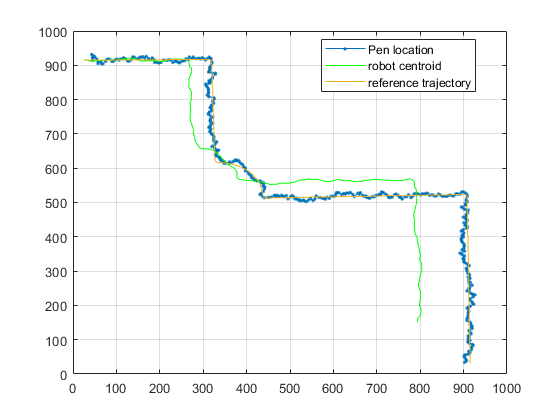

position = position;

velocity_saturation = false;
v_max = 3;
w_max = 8;

% Circle
% D = .8; k = 50; h = 0.02;
% position = importdata("position_Array.mat");

% position = importdata("CharlotteLogo.mat");
% D =90; k =10; h = .02;
% position  = position';

l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
      
state(:,1) =[position(1,1); position(2,1); 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;

for t =1 : T
    n1 = 10*randn(1);
    n2 = 10*randn(1);
    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    v = v+n1;
    w = w+n2;
    
    if velocity_saturation == 1
        if v > v_max
            v = v_max;
        elseif v < -v_max
            v = -v_max;
        end
    end
        
    if velocity_saturation == 1   
        if w > w_max
            w = w_max;
        elseif w < -w_max
            w = -w_max;
        end
    end
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w);
    
     linear_vel(t) = v;
     angular_vel(t) = w;
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v)*cos(state(3,t)); (v)*sin(state(3,t)); w];
    
end

x = [xb; yb];
save("map_noise_pen.mat","x")

figure
plot(xb, yb, '.-')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:));
grid on;
legend('Pen location', 'robot centroid', 'reference trajectory', "location", 'best')
hold off


figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('linear velocity (v)', 'angular velocity (w)')
c = 1

c = 1

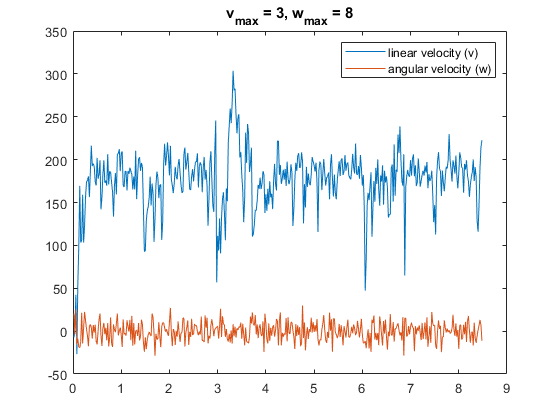

title("v_{max} = " + v_max + ", w_{max} = " + w_max)

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];

v_feedback = [xVelocity; yVelocity] - k*( x(1:2,1)- [position(1); position(2)]);

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v; w];

end